# PHSCS 530: Optimization Homework

## Problem 1: Washboard Potential

### Part A

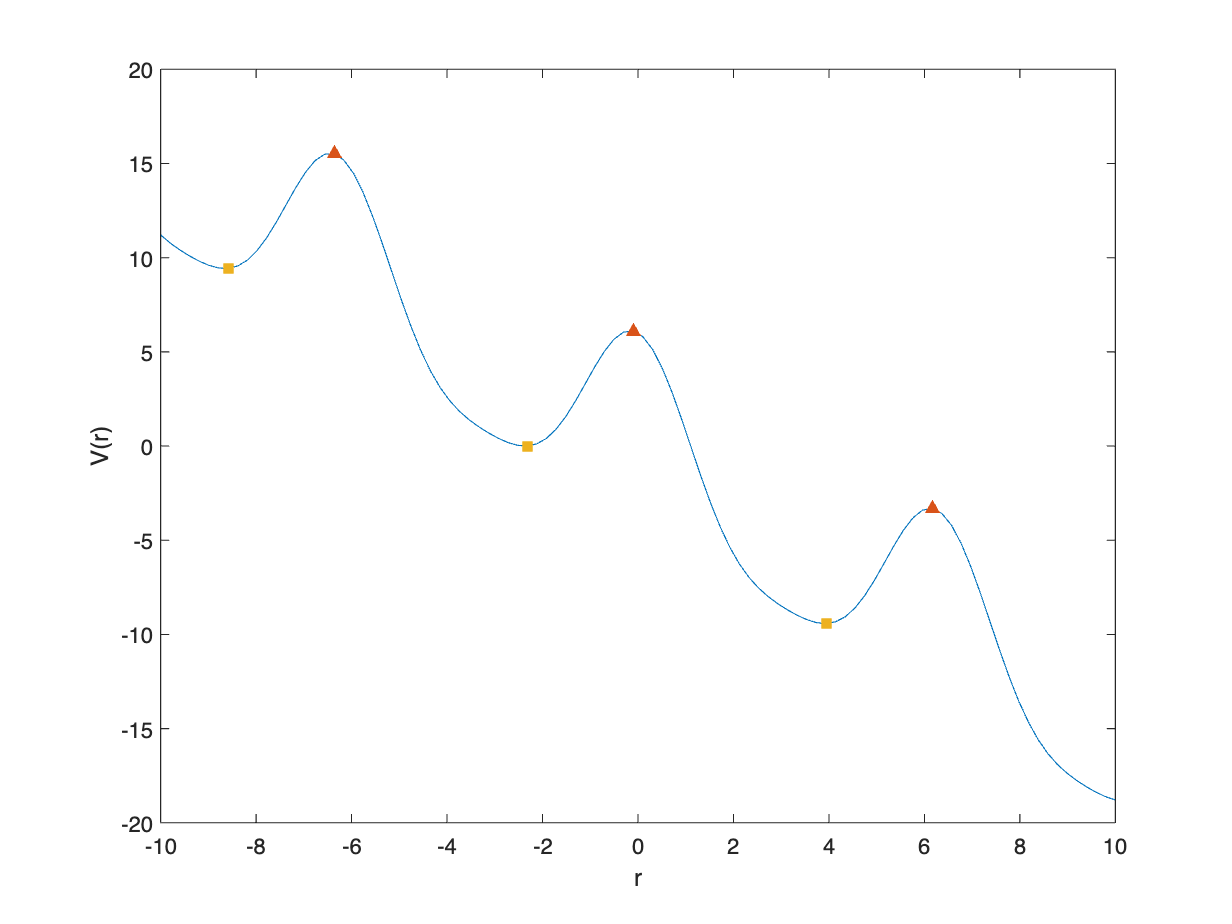

V = @(r,A1,A2,F) A1*cos(r) + A2*cos(2*r) - F*r;
A1 = 5;
A2 = 1;
F = 1.5;

r = linspace(-10,10);
Vr = V(r,A1,A2,F);

figure
plot(r,V(r,A1,A2,F))
xlabel('r')
ylabel('V(r)')

% u\Use findpeaks to find local minima and maxima
[maxs,indmax] = findpeaks(Vr);
[mins,indmin] = findpeaks(-Vr);

hold on
scatter(r(indmax),maxs,'^','filled')
scatter(r(indmin),-mins,'s','filled')
hold off


% Potential difference between second local max and min
Vdiff = Vr(indmax(2)) - Vr(indmin(2))

Vdiff = 6.1038

### Part B

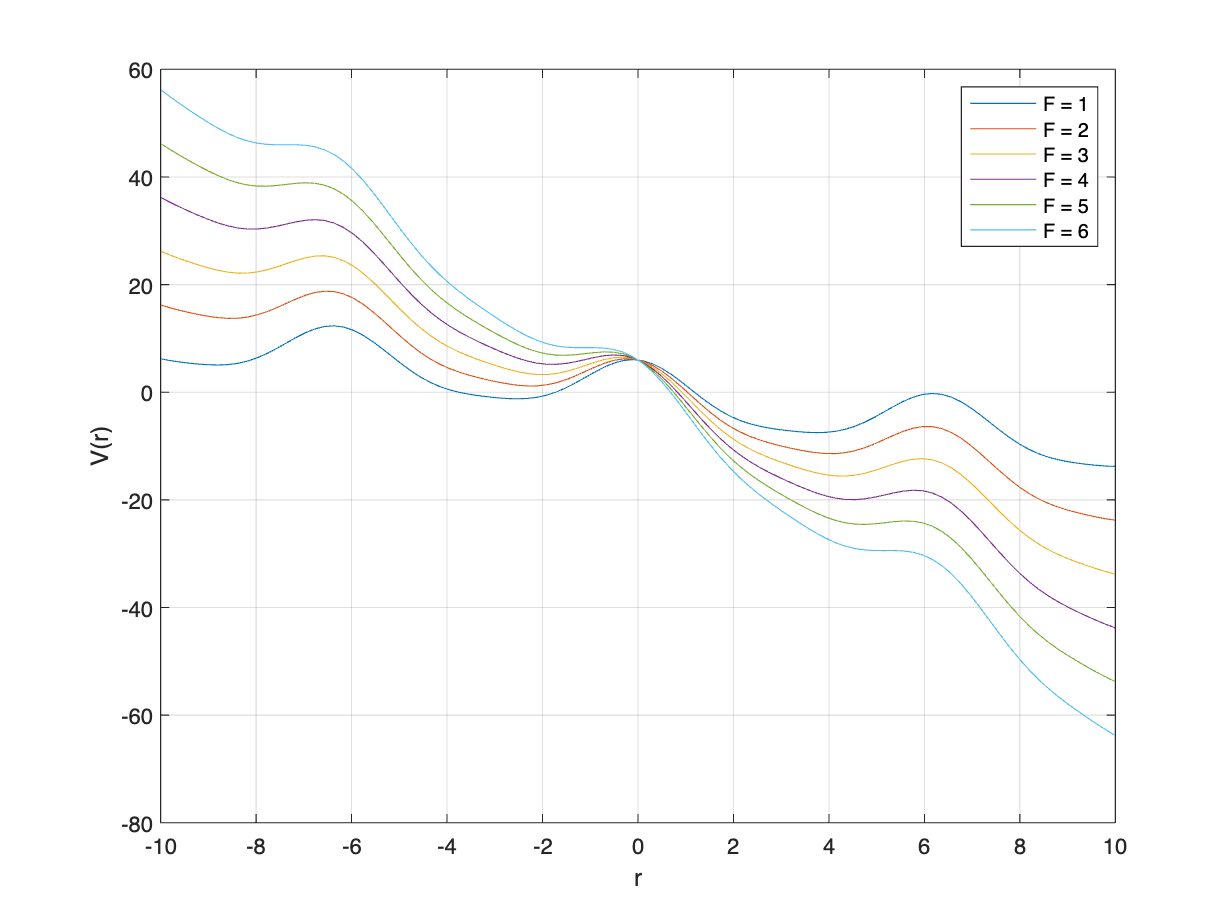

Fs = linspace(1,6,6);
figure
hold on
for i = 1:length(Fs)
    plot(r,V(r,A1,A2,Fs(i)),'DisplayName',['F = ',num2str(Fs(i))])
end
hold off
legend
grid on
xlabel('r')
ylabel('V(r)')
box on

It appears that $F_c \approx 6$.

## Problem 2: Sloppy Minimization

### Part A

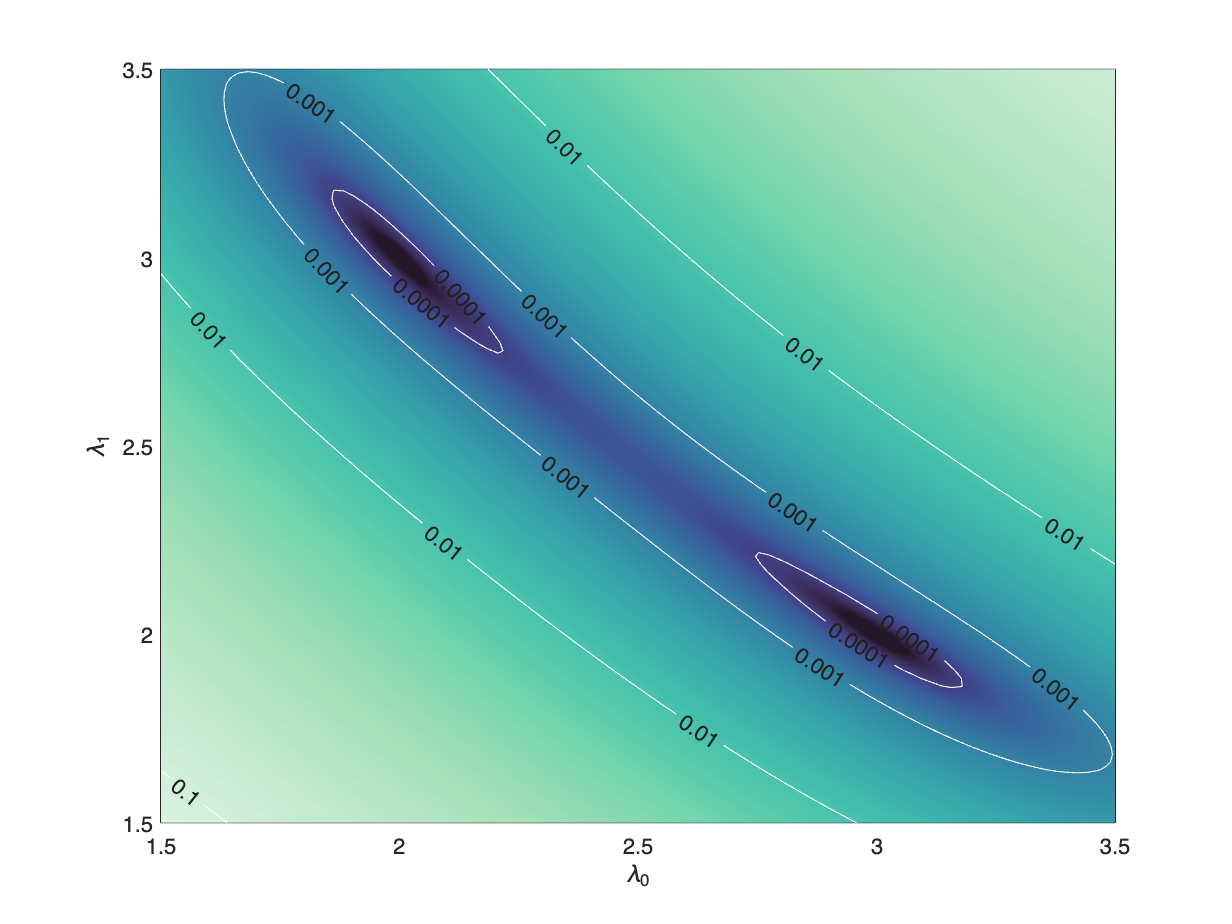

y = @(t,N,lambda) 1/N * sum(lambda .* exp(-lambda.*t));

lambda = [2,3];

C = @(lambda0,lambda1) -51/40 + lambda0/8 - lambda0./(2+lambda0) - ...
    3*lambda0./(2*(3+lambda0)) + lambda1/8 + 2./(2+lambda1) + ...
    9./(2*(3+lambda1)) + lambda0.*lambda1./(2*(lambda0+lambda1));

lambdan = linspace(1.5,3.5,100);
[LAMBDA0,LAMBDA1] = meshgrid(lambdan,lambdan);

levels = logspace(-1,-4,4);

figure
pcolor(LAMBDA0,LAMBDA1,C(LAMBDA0,LAMBDA1))
hold on
contour(LAMBDA0,LAMBDA1,C(LAMBDA0,LAMBDA1),levels,'-w','ShowText','on')
colormap mako
shading interp
set(gca,'ColorScale','log') % set logarithmic colorscale
xlabel('\lambda_0')
ylabel('\lambda_1')

### Part B

% One-dimensional function to optimize, assuming \lambda_1 = \lambda_2
C1D = @(x) -51/40 + x/8 - x./(2+x) - ...
    3*x./(2*(3+x)) + x/8 + 2./(2+x) + ...
    9./(2*(3+x)) + x.*x./(2*(x+x));
% use MATLAB fminbnd from Optimization Toolbox to find one-dimensional
% bounded minimum
lambdaOpt = fminbnd(C1D,1.5,3.5);
disp(['The optimal single-exponent fit is \lambda = ',num2str(lambdaOpt)])

The optimal single-exponent fit is \lambda = 2.4749


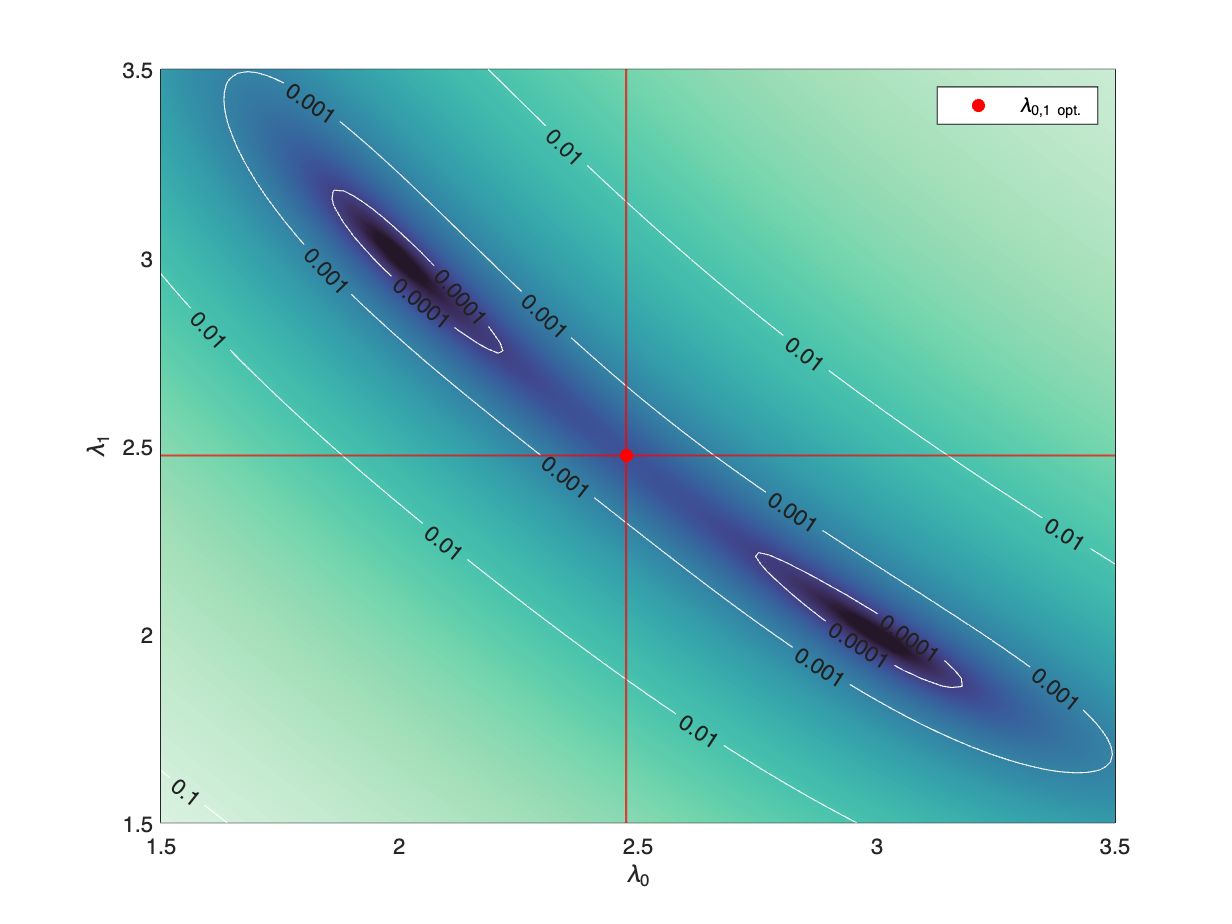

% plot the optimal single-exponent fit on the contour plot
figure
pcolor(LAMBDA0,LAMBDA1,C(LAMBDA0,LAMBDA1))
hold on
contour(LAMBDA0,LAMBDA1,C(LAMBDA0,LAMBDA1),levels,'-w','ShowText','on')
colormap mako
shading interp
set(gca,'ColorScale','log') % set logarithmic colorscale
xlabel('\lambda_0')
ylabel('\lambda_1')
scatter(lambdaOpt,lambdaOpt,'ro','filled')
legend('','','\lambda_{0,1 opt.}','AutoUpdate','off')
xline(lambdaOpt,'-r','LineWidth',1)
yline(lambdaOpt,'-r','LineWidth',1)
hold off

### Part C

## Problem 3: Convex Functions

### Part A

### Part B

## Problem 4: Convex Optimization

Minimize $\min_x {\;\left\|J\left(x-x_0 \right)\right\|}_2^2 +\lambda \;{\left\|x\right\|}_1$ subject to $x_i \ge 0$

### Part A

J = readmatrix('J.txt');
x0 = readmatrix('x0.txt');

lambda = 0;
cvx_begin

Dot indexing is not supported for variables of this type.

Error in cvx_global (line 76)
osolvers = cvx___.solvers.list;

Error in cvxprob (line 4)
cvx_global

Error in cvx_begin (

    variable x(n)
    minimize (norm(J*(x-x0),2)^2 + lambda*norm(x,1))
    x >= 0;
cvx_end

### Part B